# 2D Convolution and Image Filtering - SS, lab 10

Zeic Beniamin

## Exercise 1

### 1a. Analytical convolution

The files for this convolution operation can be found at the end of this pdf file

### 1b. Convolve using *imfilter*

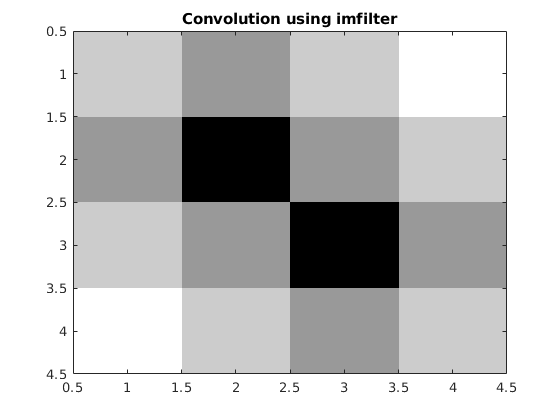

A = [ 0 16 32 48;
     16  0 16 32;
     32 16  0 16;
     48 32 16  0];

k = 1/9*ones(3,3); % K needs no rotation since all its elements are equal
resultb = imfilter(A, k, 'conv', 'circular');
colormap('gray'); imagesc(resultb); title("Convolution using imfilter");

### 1c. Matlab function for convolution of 2D image with 2D kernel

The function convolve() is defined at the end of the live script.

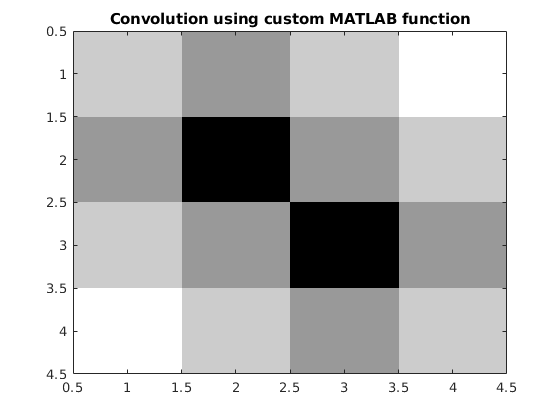

% convolve() function defined at the end of the live script
imagesc(convolve(A, k));
title("Convolution using custom MATLAB function");

## Exercise 2

### 1a Import image

% Get the image and convert it to grayscale (i.e. 2D image)
peppers = imread('peppers.png');
peppers = rgb2gray(peppers);
% Define the kernels to be used
% Gaussian and motion blur   

### 1b Apply filters

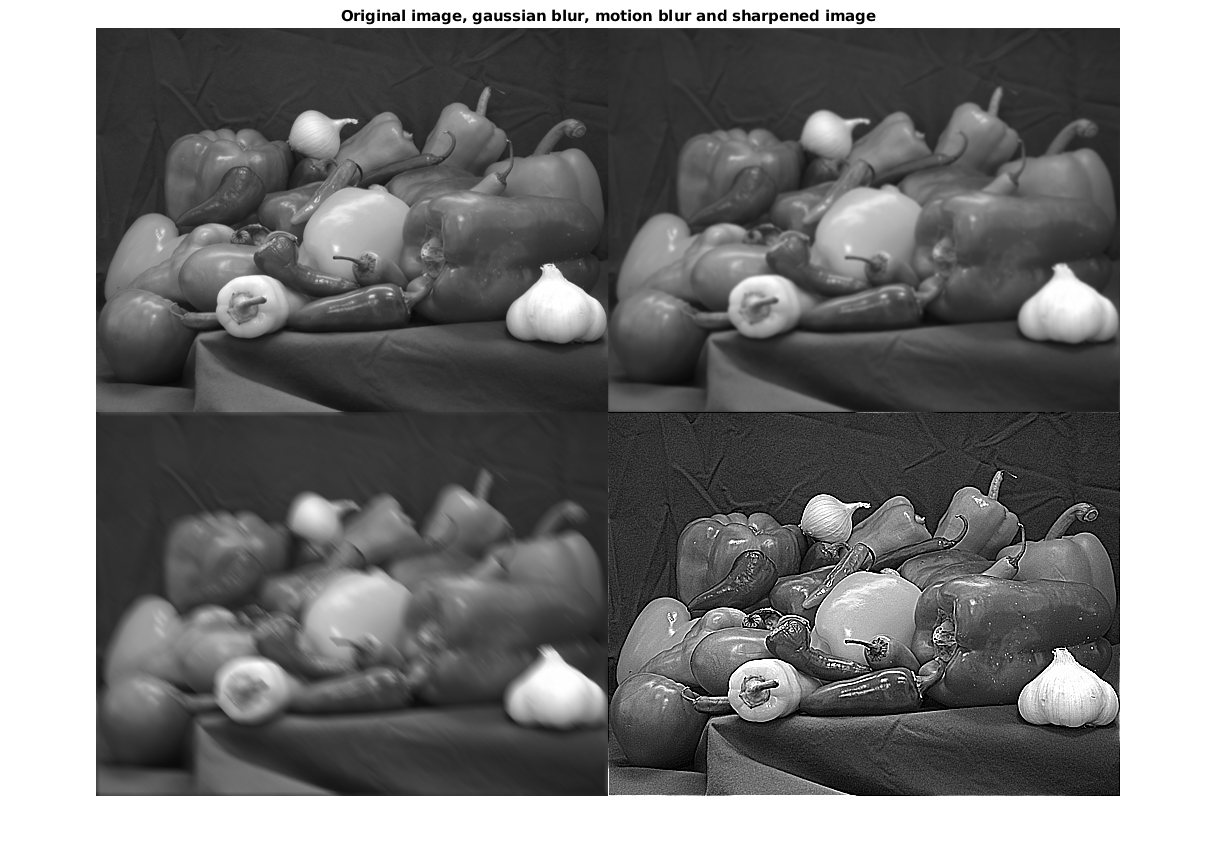

h_gauss_blur = 1/256*[ 1  4  6  4  1;
                       4 16 24 16  4;
                       6 24 36 24  6;
                       4 16 24 16  4;
                       1  4  6  4  1;];

h_motion_blur = zeros(9,9);
for i=1:length(h_motion_blur)
    for j=1:length(h_motion_blur)
        if (i == j)
            h_motion_blur(i,j) = 1;
        end
    end
end
h_motion_blur = h_motion_blur/9;

% Sharpening filter
h_sharp = [-1 -1 -1;
           -1  9 -1;
           -1 -1 -1;];

% Laplacians for edge and line detection
h_edge = [-1 -1 -1;
          -1  8 -1;
          -1 -1 -1;];
h_horiz_line = [-1 -1 -1;
                 2  2  2;
                -1 -1 -1;];
h_vert_line = [-1  2 -1;
               -1  2 -1;
               -1  2 -1;];
h_45deg_up = [-1 -1  2;
              -1  2 -1;
               2 -1 -1;];
h_45deg_down = [ 2 -1 -1;
                -1  2 -1;
                -1 -1  2;];

% Edge detectors - Sobel and Prewitt
h_horiz_sobel = [ 1  2  1;
                  0  0  0;
                  -1 -2 -1];
h_vert_sobel = [ 1  0 -1;
                 2  0 -2;
                 1  0 -1;];

h_horiz_prew = [ 1  1  1;
                 0  0  0;
                -1 -1 -1;];
h_vert_prew = [ 1  0 -1;
                1  0 -1;
                1  0 -1;];

pep_gauss_blur = imfilter(peppers, h_gauss_blur, 'conv', 'circular');
pep_motion_blur = imfilter(peppers, h_motion_blur, 'conv', 'circular');
pep_sharpened = imfilter(peppers, h_sharp, 'conv', 'circular');

pep_lapl_edge = imfilter(peppers, h_edge, 'conv', 'circular');
pep_lapl_horiz = imfilter(peppers, h_horiz_line, 'conv', 'circular');
pep_lapl_vert = imfilter(peppers, h_vert_line, 'conv', 'circular');
pep_lapl45_up = imfilter(peppers, h_45deg_up, 'conv', 'circular');
pep_lapl45_down = imfilter(peppers, h_45deg_down, 'conv', 'circular');

pep_horiz_sobel = imfilter(peppers, h_horiz_sobel, 'conv', 'circular');
pep_vert_sobel = imfilter(peppers, h_vert_sobel, 'conv', 'circular');
pep_horiz_prew = imfilter(peppers, h_horiz_prew, 'conv', 'circular');
pep_vert_prew = imfilter(peppers, h_vert_prew, 'conv', 'circular');

imshow([peppers         pep_gauss_blur;
        pep_motion_blur pep_sharpened;])
title("Original image, gaussian blur, motion blur and sharpened image")

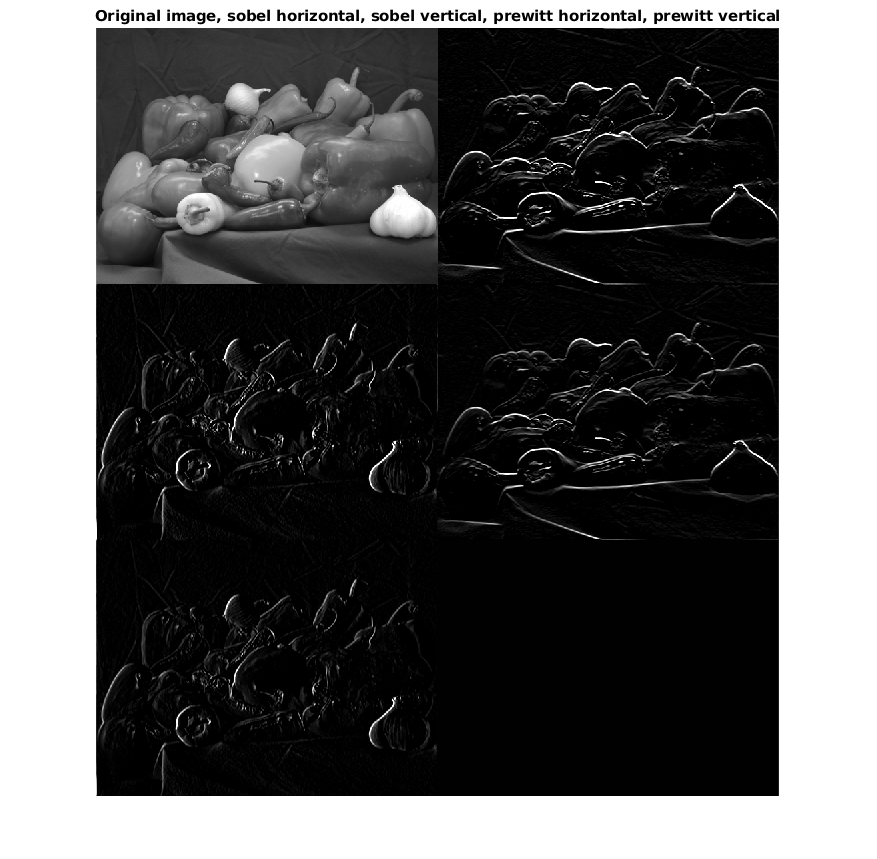


imshow([peppers         pep_horiz_sobel;
        pep_vert_sobel  pep_horiz_prew;
        pep_vert_prew   ones(height(peppers), width(peppers))])

title("Original image, sobel horizontal, sobel vertical, prewitt horizontal, prewitt vertical")

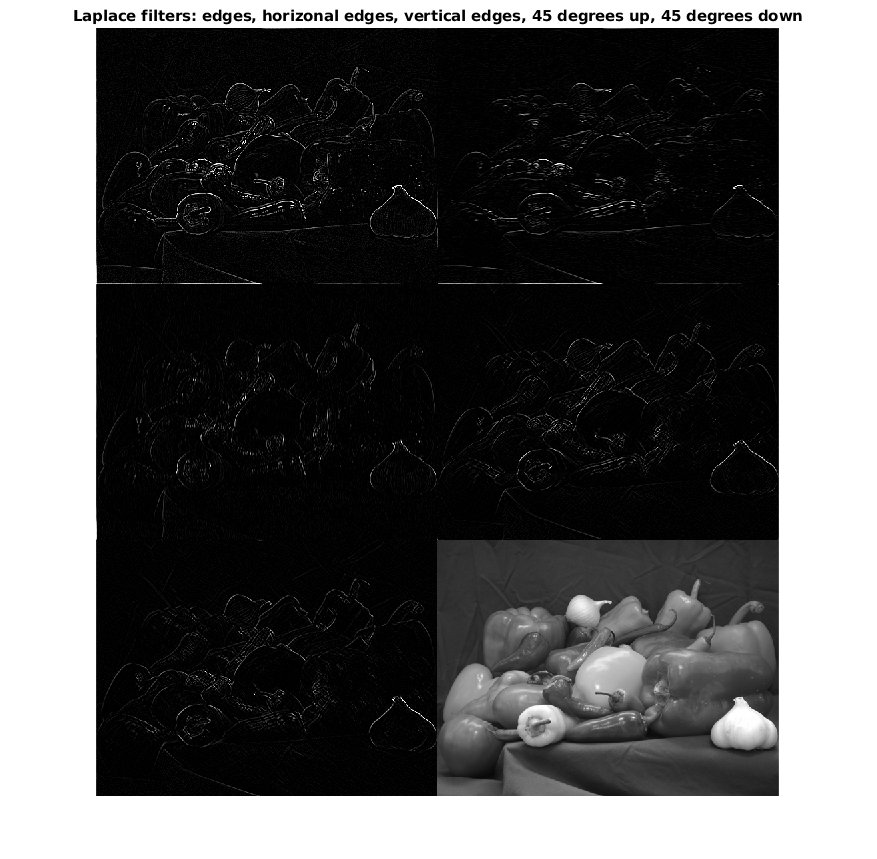

imshow([pep_lapl_edge   pep_lapl_horiz;
        pep_lapl_vert   pep_lapl45_up;
        pep_lapl45_down peppers])
title("Laplace filters: edges, horizonal edges, vertical edges, 45 degrees up, 45 degrees down")

### 1c,d Add noise and export image

noisy_pepper = imnoise(peppers, "salt & pepper");
imwrite(noisy_pepper, 'photo1_noise.jpg');

### 1e Filter the noisy image

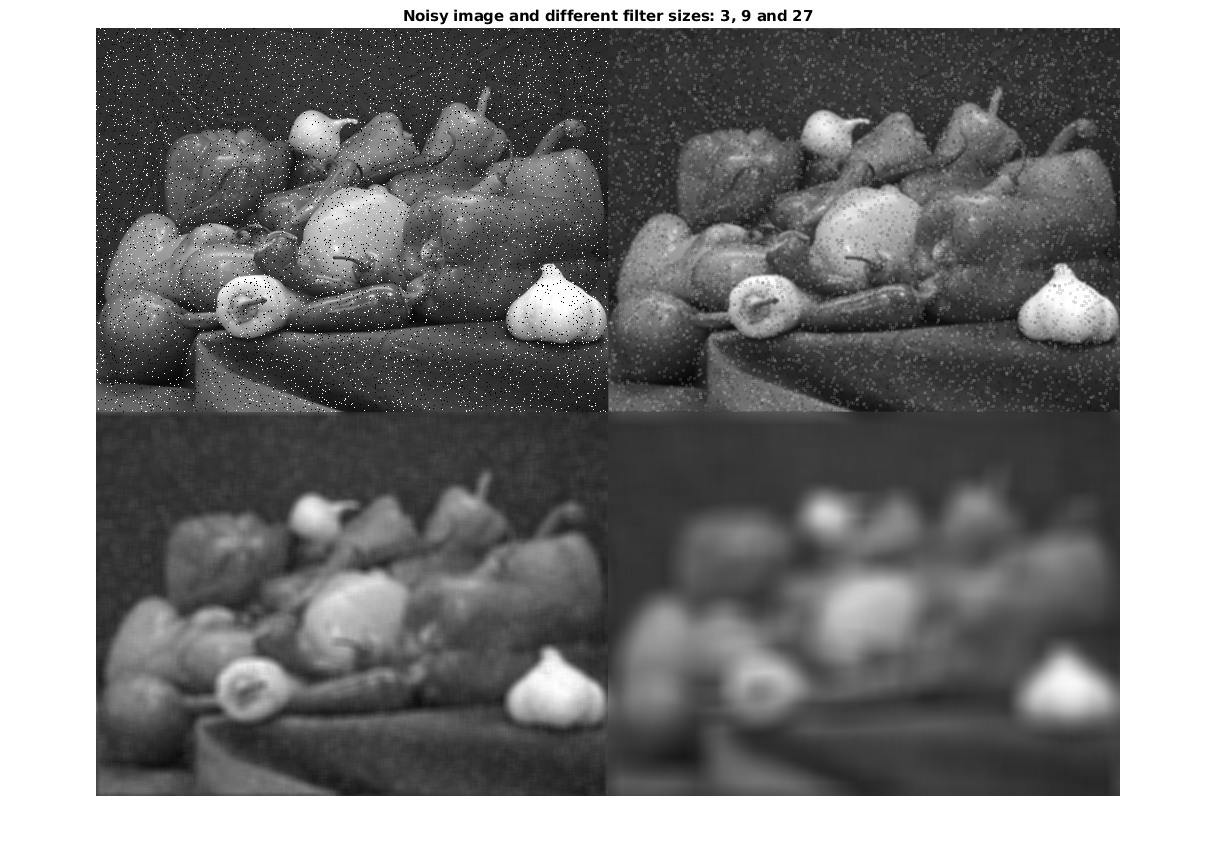

filter_size = 3;
h_1 = 1/filter_size^2*ones(filter_size); % Define different filters
filter_size = 9;
h_2 = 1/filter_size^2*ones(filter_size); 
filter_size = 27;
h_3 = 1/filter_size^2*ones(filter_size); 

imshow([noisy_pepper,...
        imfilter(noisy_pepper, h_1, 'conv', 'circular');
        imfilter(noisy_pepper, h_2, 'conv', 'circular'), ...
        imfilter(noisy_pepper, h_3, 'conv', 'circular')])
title("Noisy image and different filter sizes: 3, 9 and 27")

**We can easily observe that an increase in the size of the filter results in a larger blur applied to the image. For large values of the filter (eg: 27), we can no longer distinguish the objects in the image.**

function result = convolve(A, k)
    
    rowsA = length(A); % Get the number of rows and columns in A
    colsA = width(A);
    
    p = fix(length(k)/2); % fix() is equivalent to the DIV operation
    kcenter = p+1; % the center of the kernel has the coordinates (kc,kc)
    
    % An offset of zero results in a wrap arround padding
    % An offset different from zero ignores the 
    offset = 0;
    
    if offset == 0
        result = zeros(rowsA, colsA);
    else
        result = zeros(rowsA - 2*offset, colsA - 2*offset);
    end
    
    for i = 1+offset:rowsA-offset
        for j = 1+offset:colsA-offset
            sum = 0;
    %         B = "[" + int2str(i) + ", " + int2str(j) + "]"
            for kr = -p:p
                for kc = -p:p
                    x = i+kr;
                    y = j+kc;
                    
                    if x < 1
                        x = x + rowsA;
                    elseif x > rowsA
                        x = x - rowsA;
                    end
                    
                    if y < 1
                        y = y + colsA;
                    elseif y > colsA
                        y = y - colsA;
                    end
    %                 str = int2str(A(x,y)) + "*" + num2str(k(kcenter + kr, kcenter + kc)) + "=" + num2str(A(x,y)*k(kcenter + kr, kcenter + kc));
                    
                    sum = sum + A(x,y)*k(kcenter + kr, kcenter + kc);
                end
            end
            
    %         sum
            if offset == 0
                result(i,j) = sum;
            else
                result(i-offset, j-offset) = sum;
            end
        end
    end
    
    result; % The image resulted from convolution
end